# ELEC-8103 – Modelling, Estimation, and Dynamic Systems

# Final Exercise – Task 1 (39 points)

**Consider the magnetic suspension system shown in Figure 1. The electromagnetic coil is fixed on the floor, and the ferromagnetic bar with mass **$\mathit{\mathbf{m}}$** is suspended in the air, above the coil. The bar is controlled with the current flowing through the coil, denoted by **$\mathit{\mathbf{i}}$, **and the objective is to predict the position of the bar, represented by **$\mathit{\mathbf{z}}$**. Note that the positive direction is assumed to be upwards. The bar is connected to a fixed frame by a spring and damper with coefficients **$\mathit{\mathbf{k}}$** and **$\mathit{\mathbf{b}}$**, respectively. The neutral position of the bottom of the spring without the bar attached to it is represented by **${\mathit{\mathbf{z}}}_{\mathit{\mathbf{k}}}$.

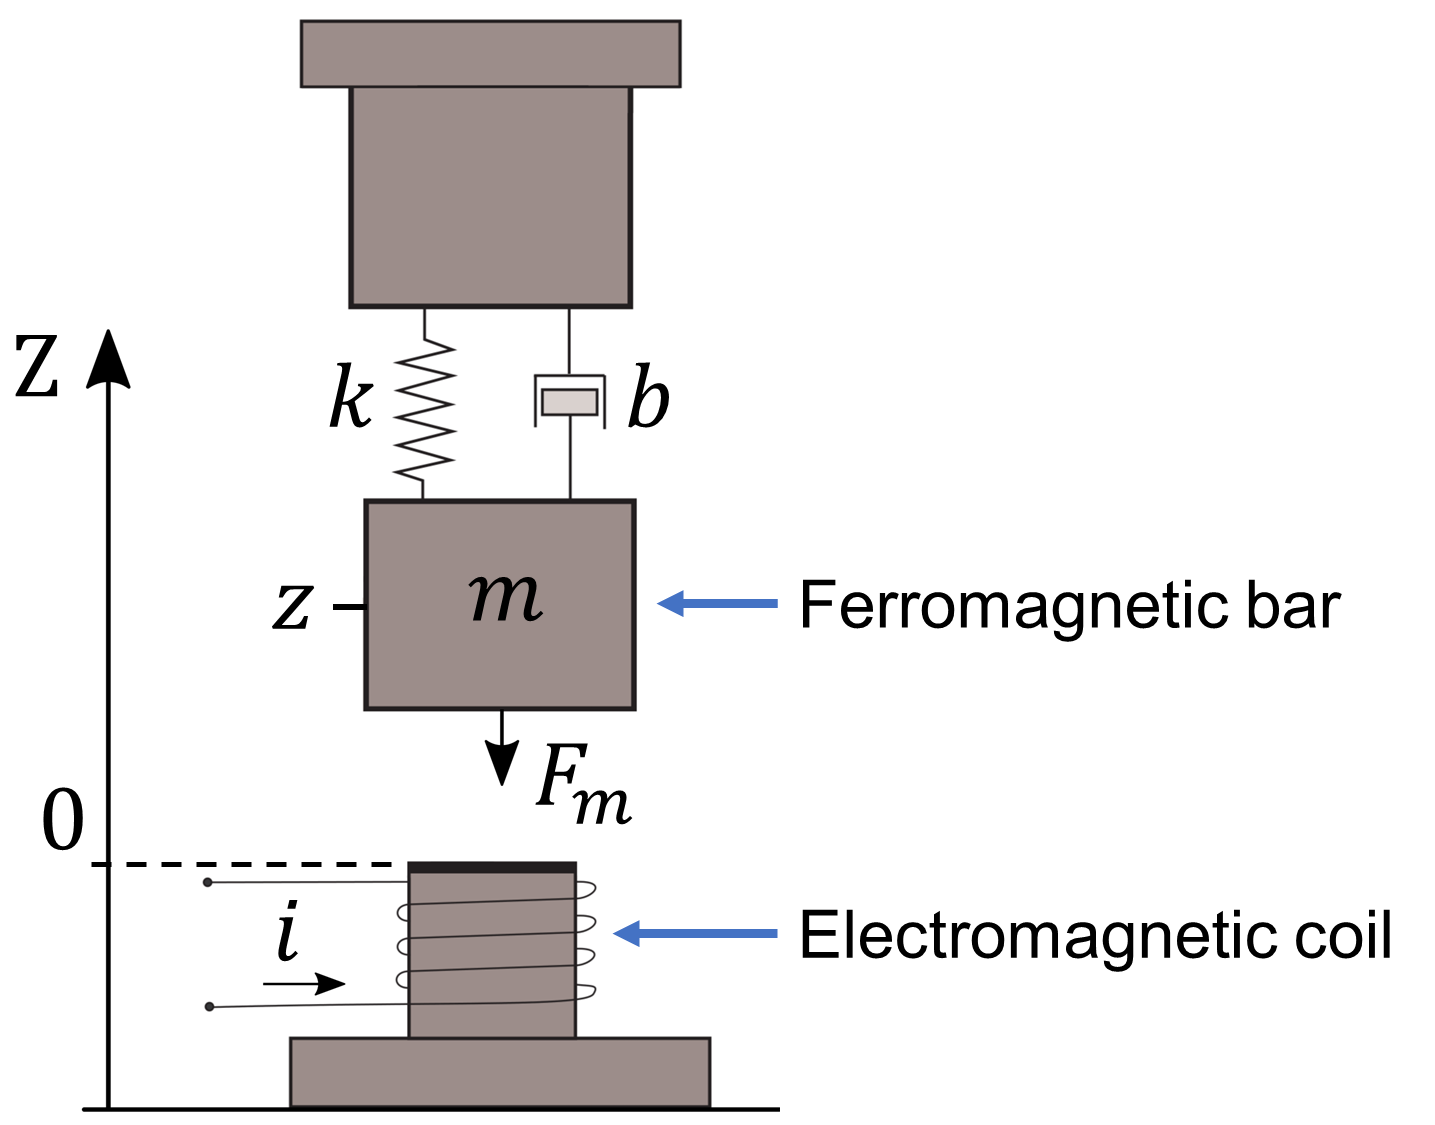

**Figure 1** – Magnetic suspension system.

**The magnetic force****, denoted by **${\mathit{\mathbf{F}}}_{\mathit{\mathbf{m}}}$**, pulls the bar downwards, i.e., in the **$-\mathbf{Z}$** direction, and is a function of the bar's position **$\mathit{\mathbf{z}}$ **and the current **$\mathit{\mathbf{i}}$**:**

### ${\mathit{\mathbf{F}}}_{\mathit{\mathbf{m}}} ={\theta_1 \left(\frac{\mathit{\mathbf{i}}}{\mathit{\mathbf{z}}+\theta_2 }\right)}^2$**,**

**where **$\theta_1$** and **$\theta_2$** are coefficients that depend on the physical properties of the bar and the coil, such as magnetic permeability, core material, geometry, size, etc.**

**The gravitational force****, which also acts on the bar in the **$-\mathbf{Z}$** direction, is not negligible and is exressed as follows,**

### ${\mathit{\mathbf{F}}}_{\mathit{\mathbf{g}}} =\mathit{\mathbf{m}}\cdot \mathit{\mathbf{g}}$,

**where **$\mathit{\mathbf{g}}$ **represents** **gravitational acceleration.**

#### a) Answer the following questions:** (1 point) **

- What signal(s) are the output(s) of the system?

- What signal(s) are the input(s) of the system?

- What are the constants of the system?

- What are the internal time-varying variables of the system?

%---------------------------------------------------------------
%                       Your Answer Below
%---------------------------------------------------------------

% Input signal(s): i

% Output signal(s): z

% Constants: k b m g theta1 theta2 zk

% Internal time-varying variables: fm 

#### **b) **Establish the fundamental equation for the system using first principles. (5 points)

Hint: You are expected to derive one differential equation that describes the motion of the bar using Newton's second law.

# 
$$\textrm{Type}\;\textrm{Equations}\;\textrm{here}$$



$$\mathrm{Eq}\ldotp \;\;mz^{\prime \prime =\;\;} k\cdot \left(z_k -z\right)-\;b\cdot z^{\prime } -m\cdot g-\mathrm{theta1}\cdot {\left(\frac{\;i}{\left(z+\mathrm{theta2}\right)}\right)}^2$$


#### **c) Is the system linear or nonlinear?** Explain in 1-2 sentences. (1 point)

%---------------------------------------------------------------
%  I think this system nonlinear,because the magnetic force is influenced
%  by i and its not satisfy the Principle of Proportionality,because the
%  calculation need to square.
%---------------------------------------------------------------


#### d) Solve the differential equation of the system: (7 points)

- **Create a function ****"odefcn" in a separate script**** to describe the equation you derived in "1-b"*****.***

- **Use the system parameter values and initial conditions specified below. The simulation time is [0 10] seconds.**

- **Assume the current (in Amperes) to be a function of time, given by**

#### 
$$i{\left(t\right)}\;=10\cdot \sin {\left(10\cdot t\right)}$$


- **Solve the differential equations using MATLAB's ODE solvers, e.g., **[**ode45**](https://se.mathworks.com/help/matlab/ref/ode45.html)**, and the function "odefcn" .**

- **Plot the position and velocity of the bar for 10 seconds**.

Hint: Double-check [Assignment 2](https://mycourses.aalto.fi/mod/folder/view.php?id=1061145) and the [documentation of ode45](https://se.mathworks.com/help/matlab/ref/ode45.html).

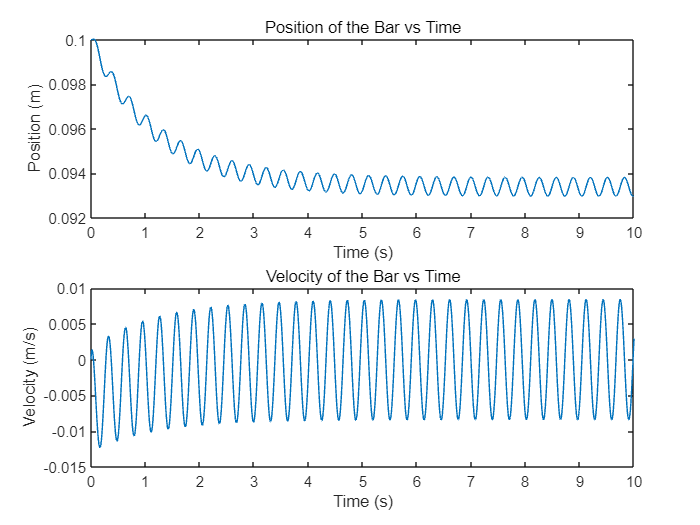

clear

% System parameters:
m = 0.1; % Mass of the bar (kg)
b = 10; % Damping coefficient (Ns/m)
k = 10; % Spring coefficient (N/m)
zk = 0.2; % Neutral position of the spring (m)
theta1 = 1.5*1e-5; % Magnetic force coefficient 1
theta2 = 0.5*1e-3; % Magnetic force coefficient 2
g = 9.81; % Gravitational acceleration (m/s^2)

% Simulation conditions:
z0 = 0.1; % Initial position of the bar (m)
v0 = 0; % Initial velocity of the bar (m/s)
init = [z0 v0]; % Initial conditions
tspan = [0 10]; % Time span

%---------------------------------------------------------------
% Define the current as a function of time
i = @(t) 10 * sin(10 * t);

% Solve the differential equations
[t, z] = ode45(@(t, z) odefcn(t, z, m, b, k, zk, theta1, theta2, g, i), tspan, init);

% Plot the results
figure;
subplot(2,1,1);
plot(t, z(:,1));
xlabel('Time (s)');
ylabel('Position (m)');
title('Position of the Bar vs Time');
subplot(2,1,2);
plot(t, z(:,2));
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity of the Bar vs Time');



%---------------------------------------------------------------

#### e)  Simulate the system using Simulink: (7 points)

- **Use the same initial conditions and parameter values as well as the current function as specified in section “1-d” above.**

- **Plot the position and velocity of the bar for 10 seconds**. **Insert the plot below.**

- **Save your Simulink model with the filename “Task1_Simulink.mdl”.**

Hint: To insert the plot, you can simply take a snapshot of the plot in the Scope block and click INSERT→IMAGE in the top toolbar. 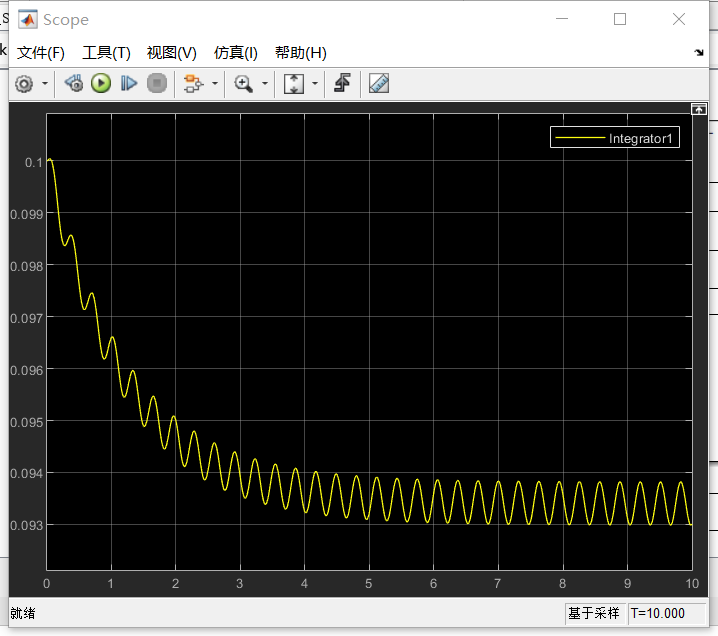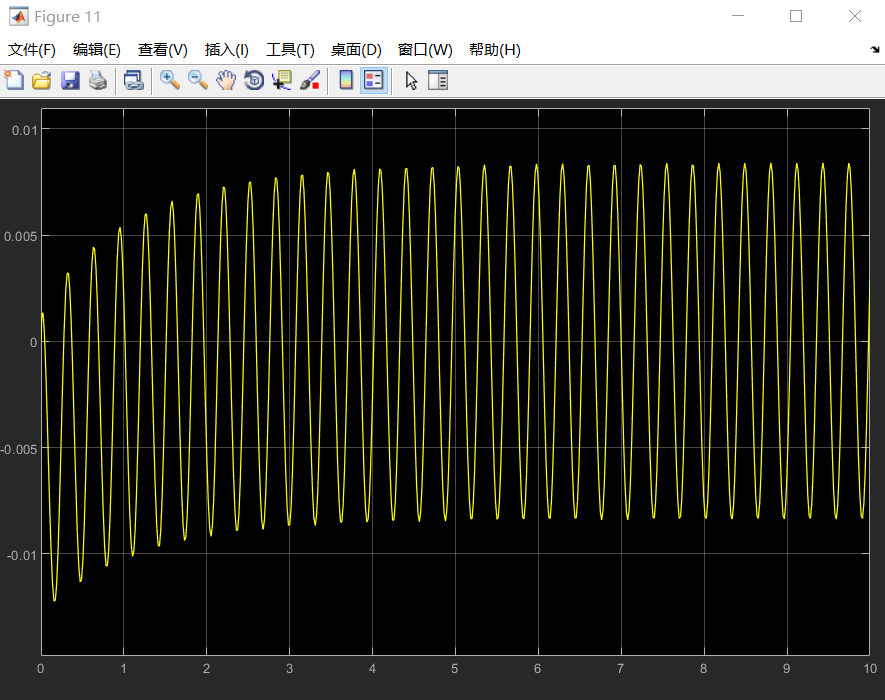

#### f)  Find the constant input current, ${\mathit{\mathbf{i}}}_{\textrm{eq}}$, required to maintain the system at a stationary point, with the magnet's position at ${\mathit{\mathbf{z}}}_{\textrm{eq}} =0\ldotp 08$ (m) and velocity at ${\textrm{𝑧̇}}_{\textrm{eq}} =0$ (m/**s**), using **the same initial conditions and parameter values given in section “1-d”. Plot the response of the system, i.e., the magnet's position and velocity, to this input for 20 seconds. (4 points)**

Hint: This input value can be obtained either by trial and error or by solving the steady-state equation analytically.

Found Ieq: 9.697


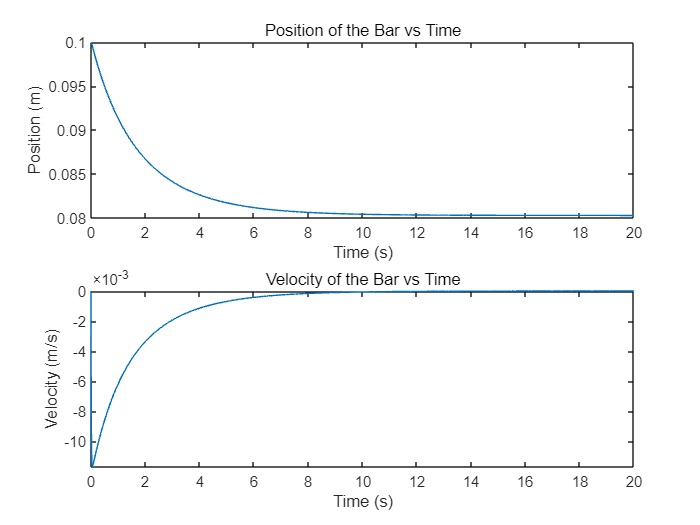

%---------------------------------------------------------------
tspan = [0 20]; % Time span for the response simulation

% Target stationary point:
zeq = 0.08; % Target position (m)
veq = 0; % Target velocity (m/s)

% Try different values for Ieq
Ieq_values = linspace(0, 10, 100); % Adjust the range and number of values as needed

for i = 1:length(Ieq_values)
    % Define the current as a function of time
    i_eq = @(t) Ieq_values(i);
    
    % Solve the differential equations
    [t_eq, z_eq] = ode45(@(t, z) odefcn(t, z, m, b, k, zk, theta1, theta2, g, i_eq), tspan, init);
    
    % Check if the system converges to the target state
    if abs(z_eq(end, 1) - zeq) < 1e-3 && abs(z_eq(end, 2) - veq) < 1e-3
        disp(['Found Ieq: ', num2str(Ieq_values(i))]);
        
        figure;
        subplot(2,1,1);
        plot(t_eq, z_eq(:,1));
        xlabel('Time (s)');
        ylabel('Position (m)');
        title('Position of the Bar vs Time');
        subplot(2,1,2);
        plot(t_eq, z_eq(:,2));
        xlabel('Time (s)');
        ylabel('Velocity (m/s)');
        title('Velocity of the Bar vs Time');
       
     
        
        break;
    end
end

%---------------------------------------------------------------

#### g)  Assume that the ferromagnetic bar (Fig. 1) has been replaced with a new one with unknown physical properties and complex geometry. Your task is to estimate the new coefficients of the magnetic force, $\theta_1$** and **$\theta_2$, using experimental data. (14 points)

- **Load the data file: **In the script below, load the “data.mat” data file. The file includes the positions of the bar $z$ (in meters) and the corresponding measurements of the magnetic force $F_m$ acting on the bar (in Newtons). During the measurements, the magnitude of the current $i$ has been fixed at 10 Amperes.

- **Estimate the coefficient values**, $\theta_1$ and $\theta_2$, based on the sum of squared errors (SSE) between the data and the magnetic force model, $F_m ={\theta_1 \left(\frac{10}{z+\theta_2 }\right)}^2$.

- **Goodness of fit**: Compute SSE and $R^2$ of your fit.

- **Visualize: **Draw the scatter plot of the data. On the same figure, plot the estimated magnetic force $F_m$ for the same values of $\mathit{\mathbf{z}}$.

Hint: You can use the function [fminsearch](https://se.mathworks.com/help/matlab/ref/fminsearch.html) or MATLAB’s Curve Fitting Toolbox.

**If you use any additional scripts for the estimation, such as Toolbox-generated code or an implemented cost function, please save and return them as well.**

clear
% Load data
load('data.mat');

I_fix = 10;

theta_initial = [1e-5, 1e-3];

objective_function = @(theta) sum((theta(1) * (10 ./ (z + theta(2))).^2 - Fm).^2);

theta_estimate = fminsearch(objective_function, theta_initial);

disp(['Estimated theta1: ', num2str(theta_estimate(1))]);

Estimated theta1: 7.5574e-05


disp(['Estimated theta2: ', num2str(theta_estimate(2))]);

Estimated theta2: 0.0060301



sse = objective_function(theta_estimate);
rsquared = 1 - sse / sum((Fm - mean(Fm)).^2);
disp(['Sum of Squared Errors (SSE): ', num2str(sse)]);

Sum of Squared Errors (SSE): 129.2182


disp(['R-squared: ', num2str(rsquared)]);

R-squared: 0.98966


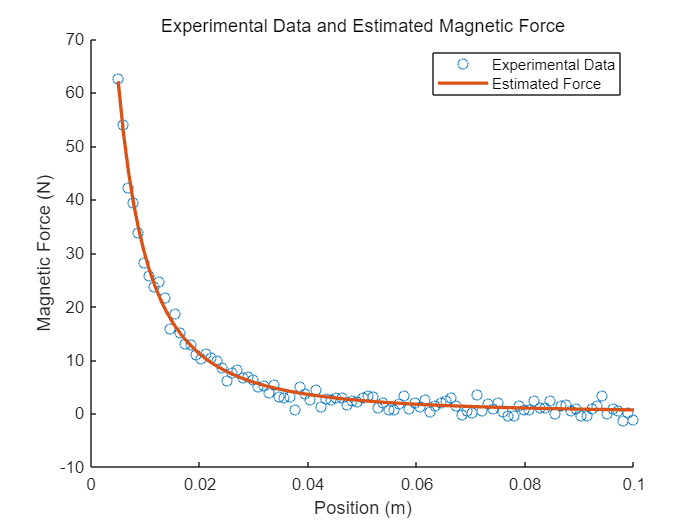

figure;
scatter(z, Fm, 'o', 'DisplayName', 'Experimental Data');
hold on;
estimated_force = theta_estimate(1) * (10 ./ (z + theta_estimate(2))).^2;
plot(z, estimated_force, 'LineWidth', 2, 'DisplayName', 'Estimated Force');
xlabel('Position (m)');
ylabel('Magnetic Force (N)');
title('Experimental Data and Estimated Magnetic Force');
legend('show');


%---------------------------------------------------------------

# **What to return?**

For this task, you are expected to submit the following files to the related link for Final Exercise on MyCourses:

- One completed .mlx file: **Task1.mlx**

- One MATLAB script: **odefcn.m**

- One Simulink file:** Task1_Simulink.mdl**

- All additional script(s) you may have used for estimation in section "1-g" (optional)